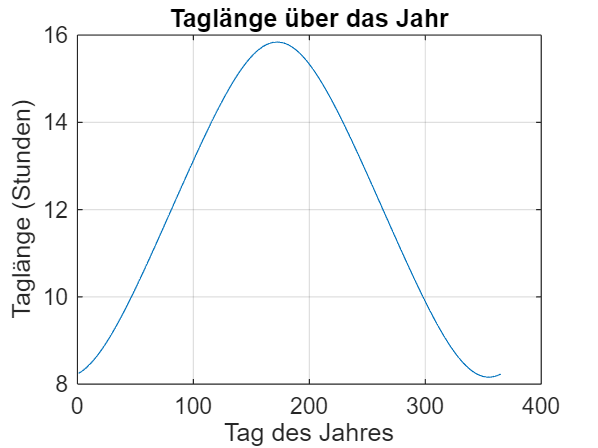

%Berechnung des Zeitpunkts von Sonnenaufgang und Sonnenuntergang
phi = 48;

berechne_deklination = @(doy) 23.45 * sind((360 / 365) * (doy + 284));

funktion_sonnenwinkel = @(t, phi, delta) sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(15 * (t - 12));

function [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta)
    sonnenaufgang = fzero(@(t) sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(15 * (t - 12)), [0, 12]);
    sonnenuntergang = fzero(@(t) sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(15 * (t - 12)), [12, 24]);
end

tage = 1:365;
taglaengen = zeros(size(tage));

for i = 1:length(tage)
    delta = berechne_deklination(tage(i));
    [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
    taglaengen(i) = sonnenuntergang - sonnenaufgang;
end

%Plot der Tagelaengen uebers Jahr

figure;
plot(tage, taglaengen);
title('Taglängen uebers Jahr');
xlabel('Tag des Jahres');
ylabel('Taglänge (Stunden)');
grid on;


% Funktion zum Einheitsvektors zur Sonne
function [x, y, z] = berechne_einheitsvektor_sonne(phi, doy, uhrzeit)
    declination = deg2rad(23.45 * sind((360 / 365) * (doy + 284))); % Deklination in Bogenmaß
    phi_rad = deg2rad(phi); % Breite in Bogenmaß
    stundenwinkel = deg2rad(15 * (uhrzeit - 12)); % Stundenwinkel in Bogenmaß
    
    x = cos(declination) * cos(stundenwinkel);
    y = cos(declination) * sin(stundenwinkel);
    z = sin(declination);
end

doy = 200; 
uhrzeit = 14; 
[x, y, z] = berechne_einheitsvektor_sonne(phi, doy, uhrzeit);

fprintf('Einheitsvektor zur Sonne um %d Uhr (Tag %d):\n', uhrzeit, doy);

Einheitsvektor zur Sonne um 14 Uhr (Tag 200):


fprintf('x: %.3f, y: %.3f, z: %.3f\n', x, y, z);

x: 0.809, y: 0.467, z: 0.356
